## RadarCubePart1.m

This program creates a radar datacube using functions from the Phased

Array System Toolbox.  This program shows 2 examples:

 1- A radar datacube with a single target, an 8 element uniform linear

 array, 1000 samples per radar pulse, and 32 pulses

 2- A radar datacube with 20 targets, a 121 element array mounted on the

 surface of a sphere, 20k samples per pulse and 32 pulses

In both cases the program is divided up into 2 sections. Section 1

defines and initializes the objects needed to build the radar data cube,

and Section 2 runs the simulation loop to generate the pulses, move the

target(s), reflect the pulses off the target and back to the radar, 

collect the received signals and build the datacube.

Copyright 2015, The MathWorks, Inc.

ULA Specs : 8 Element Uniform Linear Array with Cosine Antenna Element

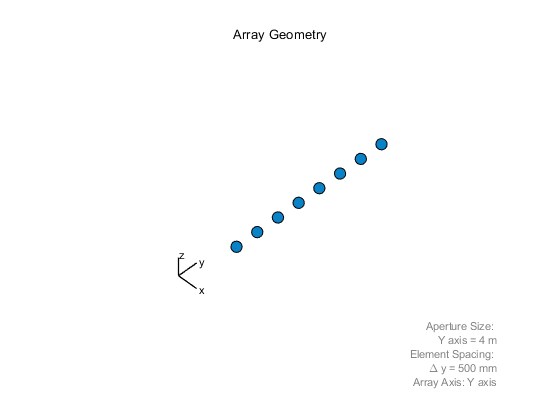

antenna=phased.ULA;
antenna.NumElements = 8;   
cosineElement = phased.CosineAntennaElement;
antenna.Element = cosineElement;
viewArray(antenna);

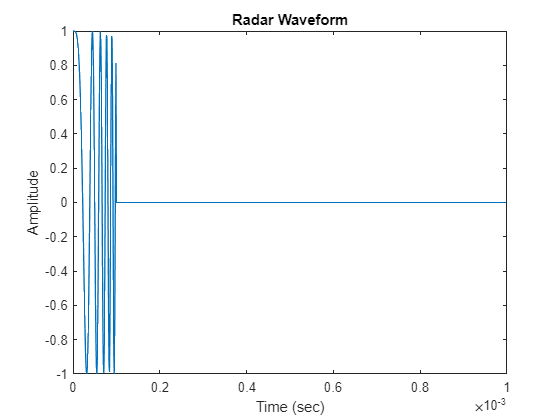

% pattern(antenna,300e6,-180:180,0,...
%     'Type','directivity',...
%     'PropagationSpeed',3e8)

% Waveform Specs
waveform=phased.LinearFMWaveform;
waveform.SampleRate = 1e6;                     % 1 MHz sample rate
waveform.PRF=1000;                             % Pulse Repetition Frequency of 1000 pulses per second
waveform.PulseWidth=1e-4;
nSamples = waveform.SampleRate/waveform.PRF;   % Define pulses on 1000 samples
y = step(waveform);
t = (0:nSamples-1)/waveform.SampleRate;
figure
plot(t,real(y));title('Radar Waveform'); xlabel('Time (sec)'); ylabel('Amplitude')

prf = waveform.PRF;

% Transmitter Specs for amplification
TX=phased.Transmitter('Gain',20);

% Target Specs
TgtModel=phased.RadarTarget;
tgtPos=[10e3*sqrt(3);10e3;0];              % Target at 20 km distance, 30 degree azimuth
tgtVel=[75*sqrt(3);75;0];                  % Radial velocity is 150 m/sec

% Platform Specs
PlatformModel=phased.Platform;
PlatformModel.InitialPosition = tgtPos;
PlatformModel.Velocity = tgtVel;

% Channel Specs
ChannelModel = phased.FreeSpace;
ChannelModel.TwoWayPropagation=true;

% Tx and Rx Array
txArray = phased.Radiator(...
    'Sensor',antenna,...
    'OperatingFrequency',300e6);
rxArray = phased.Collector(...
    'Sensor',antenna,...
    'OperatingFrequency',300e6);
rxPreamp = phased.ReceiverPreamp('Gain',10,'NoiseFigure',5,...
    'SampleRate',1e6);

% Variable definitions
radarPos = [0;0;0];
radarVel = [0;0;0];
nPulses = 32;
datacube = complex(zeros(nSamples,antenna.NumElements,nPulses));

## Generate radar pulses

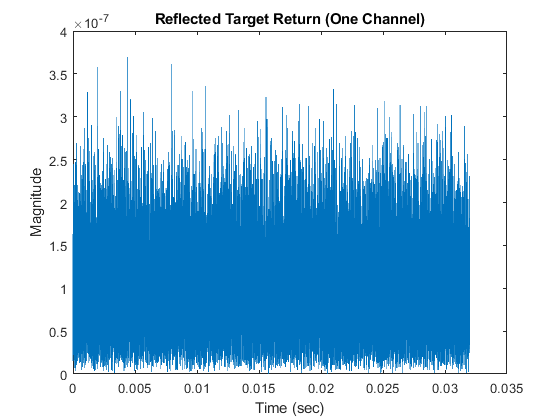

for ii=1:nPulses
    wf=step(waveform);                                                 % Generate waveform
    [tgtPos, tgtVel] = step(PlatformModel,1/prf);                      % Update target position
    [~, tgtAng] = rangeangle(tgtPos, radarPos);                        % Calculate range/angle to target
    s0 = step(TX, wf);                                                 % Amplify signal
    s1 = step(txArray,s0, tgtAng);                                     % Radiate the signal from the array
    s2 = step(ChannelModel, s1, radarPos, tgtPos, radarVel, tgtVel);   % Propagate from radar to target and return
    s3 = step(TgtModel, s2);                                           % Reflect signal from Target 
    s4 = step(rxArray,s3,tgtAng);                                      % Receive the signal at the array
    s5 = step(rxPreamp,s4);                                            % Add rx noise
    datacube(:,:,ii) = s5(:,:);                                        % Build data cube 1 pulse at a time
end
t = (0:nPulses*nSamples-1)/waveform.SampleRate;
y = abs(datacube(:,1,:));
plot(t,y(:));title('Reflected Target Return (One Channel)'); xlabel('Time (sec)'); ylabel('Magnitude')


clear 

## Simulate Targets and Element Array

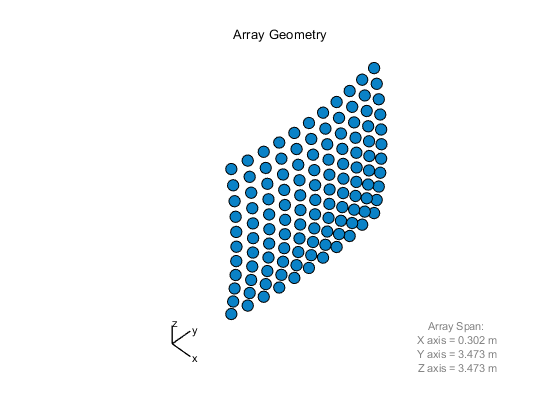

nTgt = 100;          % 20 targets with random postions, velocities and sizes
% Generate random positions, velocities and RCS values
tgtPos=[15e3+abs(randn(1,nTgt))*30e3; abs(randn(1,nTgt))*30e3;zeros(1,nTgt)];
tgtVel=[abs(randn(1,nTgt))*10e2;abs(randn(1,nTgt))*10e2;zeros(1,nTgt)];
RCS = abs(randn(nTgt, 1))';
TgtModel = phased.RadarTarget('MeanRCS',RCS);
Platform = phased.Platform('InitialPosition',tgtPos,'Velocity',tgtVel);
% Conformal Array with 121 elements mounted on a spherical surface
az = -10:2:10;
el = -10:2:10;
[ele_az, ele_el] = meshgrid(az,el);
ele_az = ele_az(:).';
ele_el = ele_el(:).';
ele_normal = [ele_az; ele_el];
N_ele = size(ele_normal,2);
[ele_x, ele_y, ele_z] = sph2cart(degtorad(ele_az),degtorad(ele_el),ones(1,N_ele));
ele_pos = [ele_x;ele_y;ele_z]*10;
% Display array geometry
antenna = phased.ConformalArray('ElementPosition',ele_pos,'ElementNormal',ele_normal);
viewArray(antenna)

nElements = getNumElements(antenna);
% Waveform Specs
waveform=phased.LinearFMWaveform;
waveform.SampleRate = 20e6;                       % 20 MHz sample rate
waveform.PRF=1000;                                % 20k samples per pulse
waveform.PulseWidth=1e-4;
prf = waveform.PRF;
nSamples = waveform.SampleRate/prf;
% Tx and Rx Specs
TX=phased.Transmitter('Gain',40);
txArray = phased.Radiator(...
    'Sensor',antenna);
rxArray = phased.Collector(...
     'Sensor',antenna);
 rxPreamp = phased.ReceiverPreamp('Gain',40,'NoiseFigure',5,...
     'SampleRate',20e6);
 
% Channel Specs
ChannelModel = phased.FreeSpace;
ChannelModel.TwoWayPropagation=true;
ChannelModel.SampleRate = waveform.SampleRate;
% Variable definitions
radarPos = [0;0;0];
radarVel = [0;0;0];
nPulses = 32;
datacube = complex(zeros(nSamples,nElements,nPulses));
tgtAng = zeros(2,nTgt);
tgtVel = zeros(3,nTgt);
tgtRng = zeros(1,nTgt);
tic

## Generate Radar Pulses and Assemble Radar Datacube

for ii=1:nPulses
    wf=step(waveform);                                                  % Generate waveform
    [tgtPos, tgtVel] = step(Platform,1/prf);                            % Update target positions
    [tgtRng, tgtAng] = rangeangle(tgtPos, radarPos);                    % Calculate range/angle to targets
    s0 = step(TX, wf);                                                  % Amplify signal
    s1 = step(txArray,s0,tgtAng);                                       % Radiate the signal from Tx array
    s2 = step(ChannelModel, s1, radarPos, tgtPos, radarVel, tgtVel);    % Propagate to target and return
    s3 = step(TgtModel, s2);                                            % Reflect signal from Target 
    s4 = step(rxArray,s3,tgtAng);                                       % Receive signal at rx array
    s5 = step(rxPreamp,s4);                                             % Add rx noise
    datacube(:,:,ii) = s5(:,:);                                         % build data cube 1 pulse at a time
end
toc

Elapsed time is 13.926042 seconds.


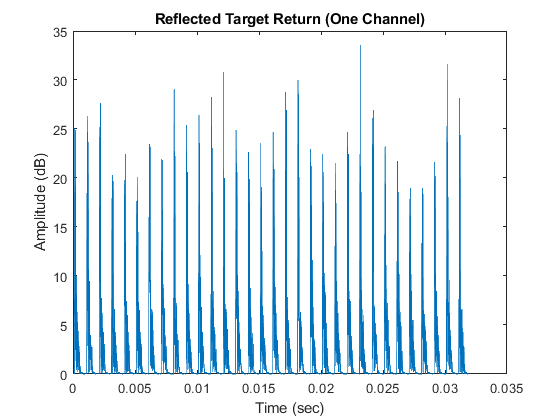

figure 
t = (0:nPulses*nSamples-1)/waveform.SampleRate;
y = abs(datacube(:,12,:))*2370*1.1;
plot(t,y(:));title('Reflected Target Return (One Channel)'); xlabel('Time (sec)'); ylabel('Amplitude (dB)')

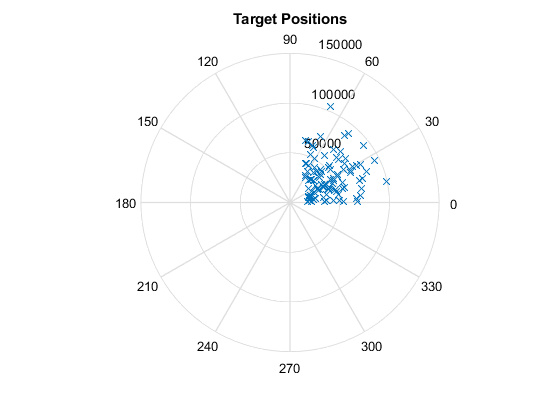

figure
[t,r]=(cart2pol(tgtPos(1,:),tgtPos(2,:),tgtPos(3,:)));
polar(t,r,'x'); title('Target Positions')

%%
% Complete